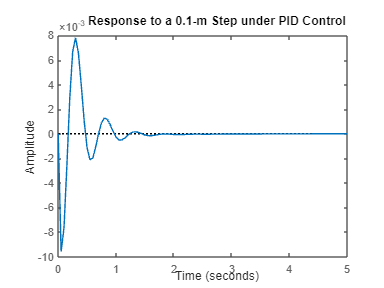

clc;
clear ;
close all;
m1 = 2500;
m2 = 320;
k1 = 80000;
k2 = 500000;
b1 = 350;
b2 = 15020;

nump=[(m1+m2) b2 k2];
denp=[(m1*m2) (m1*(b1+b2))+(m2*b1) (m1*(k1+k2))+(m2*k1)+(b1*b2) (b1*k2)+(b2*k1) k1*k2];
G1=tf(nump,denp);

num1=[-(m1*b2) -(m1*k2) 0 0];
den1=[(m1*m2) (m1*(b1+b2))+(m2*b1) (m1*(k1+k2))+(m2*k1)+(b1*b2) (b1*k2)+(b2*k1) k1*k2];
G2=tf(num1,den1);

numf=num1;
denf=nump;
F=tf(numf,denf);


Kd = 208025;
Kp = 832100;
Ki = 624075;
C = pid(Kp,Ki,Kd);
sys_cl=F*feedback(G1,C);

t=0:0.05:5;
figure(1);
step(0.1*sys_cl,t)
title('Response to a 0.1-m Step under PID Control')

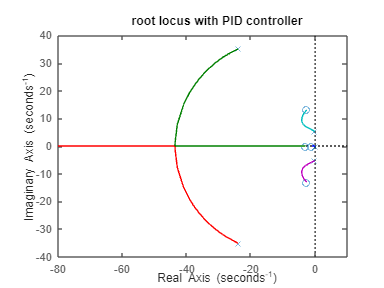


z1=1;
z2=3;
p1=0;
figure(2);
s = tf('s');
C = ((s+z1)*(s+z2))/(s+p1);
rlocus(C*G1)
title('root locus with PID controller')

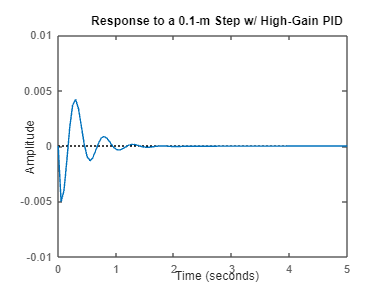



Kd=2*Kd;
Kp=2*Kp;
Ki=2*Ki;
C=pid(Kp,Ki,Kd);
sys_cl=F*feedback(G1,C);
figure(3);
step(0.1*sys_cl,t)
title('Response to a 0.1-m Step w/ High-Gain PID')
axis([0 5 -.01 .01])